**3. Considere 4 lançamentos de uma moeda equilibrada. Seja X a variável aleatória representativa do número de coroas observados nos 4 lançamentos.**

**(a) **Estime por simulação a função massa de probabilidade pX(x) da variável aleatória X.

experiencias_a = rand(4, 1e6);
sucessos_a = experiencias_a < 0.5;
quantidade_coroas = sum(sucessos_a);
casosFavoraveis_0 = sum(quantidade_coroas == 0);
casosFavoraveis_1 = sum(quantidade_coroas == 1);
casosFavoraveis_2 = sum(quantidade_coroas == 2);
casosFavoraveis_3 = sum(quantidade_coroas == 3);
casosFavoraveis_4 = sum(quantidade_coroas == 4);

prob_0 = casosFavoraveis_0/1e6

prob_0 = 0.0627

prob_1 = casosFavoraveis_1/1e6

prob_1 = 0.2499

prob_2 = casosFavoraveis_2/1e6

prob_2 = 0.3747

prob_3 = casosFavoraveis_3/1e6

prob_3 = 0.2502

prob_4 = casosFavoraveis_4/1e6

prob_4 = 0.0626

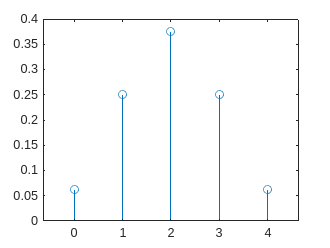


x = 0:4;
prob_x = [prob_0, prob_1, prob_2, prob_3, prob_4];
stem(x, prob_x)

**(b)** Estime o valor esperado, a variância e o desvio padrão de X com base em pX (x).

valor_esperado = sum(prob_x.*x)

valor_esperado = 2.0001

M_xx = sum(prob_x.*x.^(2))

M_xx = 5.0016

var_x = M_xx - valor_esperado^2

var_x = 1.0010

desvio_padrao = sqrt(var_x)

desvio_padrao = 1.0005

**(c)** Identifique o tipo da distribuição da variável aleatória X e escreva a expressão teórica da respetiva função de probabilidade.